**Question 6**

*Load the signal in data.mat, which you can find in assignmentPCA.7z. The signal data is a 12-lead (12 channels) ECG recording sampled at 1KHz (samples on rows and leads on columns). The signal has been acquired from a patient affected by atrial fibrillation.*

- *Consider data. Perform PCA on data, by focusing on their variance, by means of Singular Value Decomposition (look at the documentation of the Matlab function svd, and consider using [U, S, V] = svd(data,'econ');), to find out A and Z (based on the SVD model presented in class).*

- *How could you obtain an approximation of the cardiac beat (the peaks in the ECG signals) by exploiting the results at the previous point? Remember how PCA can be used to reduce the dimensionality of a dataset by compressing the information in few components describing most of the variance in the original dataset.*

- *It is known that atrial fibrillation is characterized by a dominant frequency in the range [4; 10] Hz. With this knowledge, propose a way both to estimate the value of the dominant frequency of the atrial fibrillation in the ECG recordings under analysis, and to reconstruct the original ECG recordings only by using the PCs with a dominant peak in the range [4; 10] Hz*

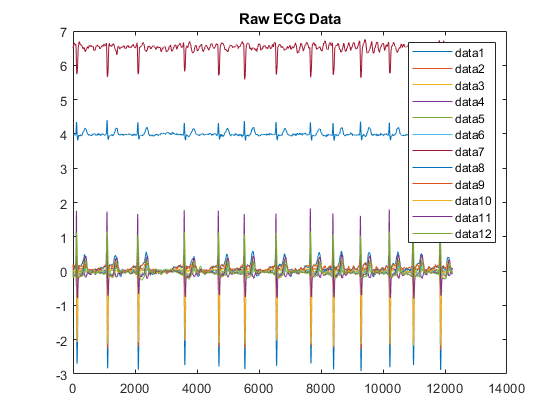

load("data.mat") %loaded into variable data

mdata = mean(data,2);

data0 = data - mdata;

figure
plot((1:length(data)),data)
title('Raw ECG Data')
legend()

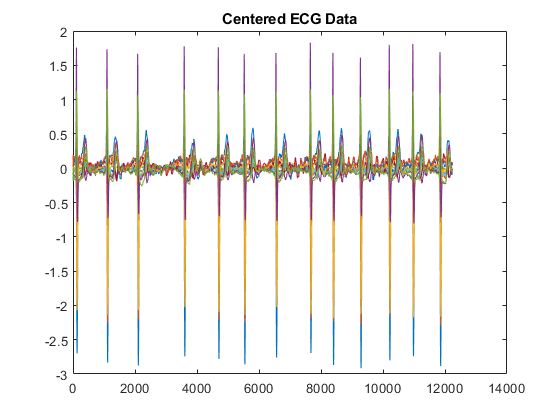


figure()
plot((1:length(data)),data0)
title('Centered ECG Data')

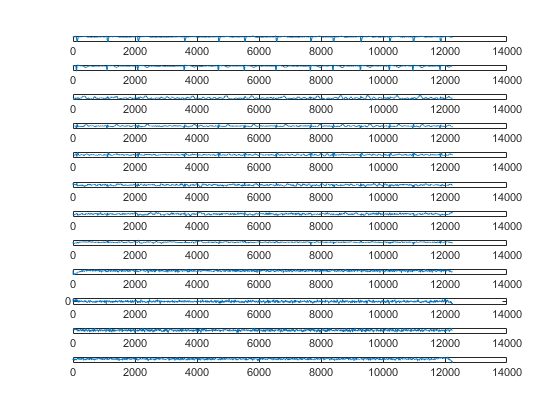

[U,S,V] = svd(data0,'econ');

A = sqrt(length(data)-1)^(-1)*(U*S);
Z = sqrt(length(data)-1)*V';

figure()
for i = 1:12
    subplot(12,1,i)
    plot((1:length(Z)),Z(i,:))
end

**HOW TO CALCULATE WHAT PERCENTAGE OF VARIANCE EACH PC TAKES! CAN BE DONE WITH EVD OR SVD**

Here we just recreate an eigenvalue decomposition, with Y the eigenvector matrix and O the Eigenvalue diagonal matrix

N = length(data0);
Rx = data0*data0'/(N-1);
[Y,O] = eig(Rx);

SVDpercent = diag(S)'.^2/sum(diag(S).^2)

ans =     0.7644    0.2094    0.0131    0.0076    0.0035    0.0011    0.0007    0.0002    0.0000    0.0000    0.0000    0.0000


EVDpercent = diag(rot90(O,2))'/sum(diag(O))

ans =     0.7644    0.2094    0.0131    0.0076    0.0035    0.0011    0.0007    0.0002    0.0000    0.0000    0.0000    0.0000


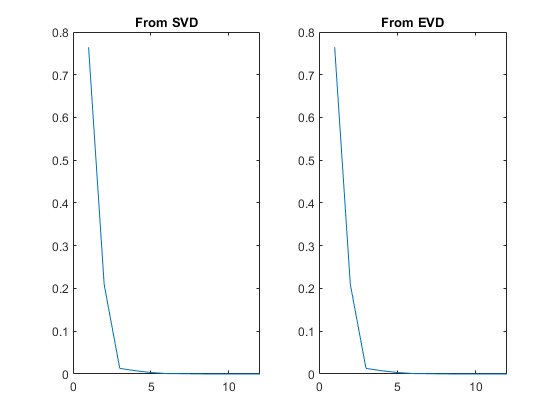

figure()
subplot(1,2,1)
plot((1:12),diag(S).^2/sum(diag(S).^2))
title("From SVD")
subplot(1,2,2)
plot((1:12),diag(rot90(O,2))/sum(diag(O)))
title("From EVD")

ECG has three main components:

- Atrial Activity 

- Ventricular Activity

- Other Noise and Artifacts

1st PC and 2nd PC measure the Ventricular activity annd Atrial is generally found in PC3-4. The QRS-T complexe is generally thought to be represented by the three first PCs.

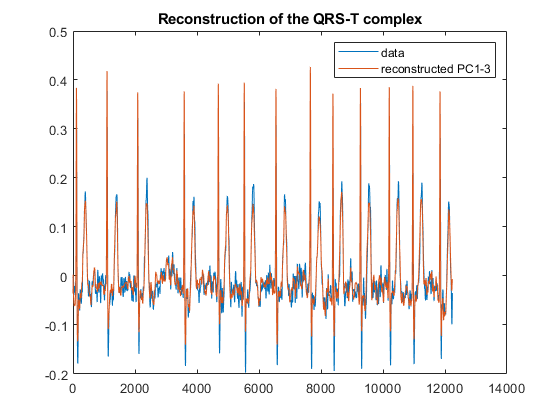

ecg_rec = A(:,1:3)*pinv(A(:,1:3))*data0;

figure()
plot((1:length(data0)),data0(1,:))
hold on
plot((1:length(ecg_rec)),ecg_rec(1,:))
hold off
legend('data','reconstructed PC1-3')
title('Reconstruction of the QRS-T complex')

We will now perform Fourier transforms on the first 5 PCs and look at their frequency spectrum. We'll see if any of them match atrial fibrilation (it should be found on PC3-4.

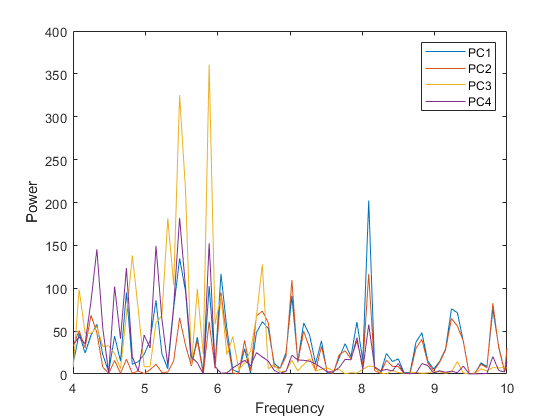

Fs = 1000;
f1 = fft(Z')';
n = length(f1);
f = (0:n-1)*(Fs/n); %freq range
power = abs(f1).^2/n;
figure()
plot(f,power(1:4,:))
xlabel('Frequency')
ylabel('Power')
legend('PC1','PC2','PC3','PC4')
axis([4 10 0 400])

So we see that the most proeminent peaking in the [4:10]Hz range is the PC3. Let's reconstruct it:

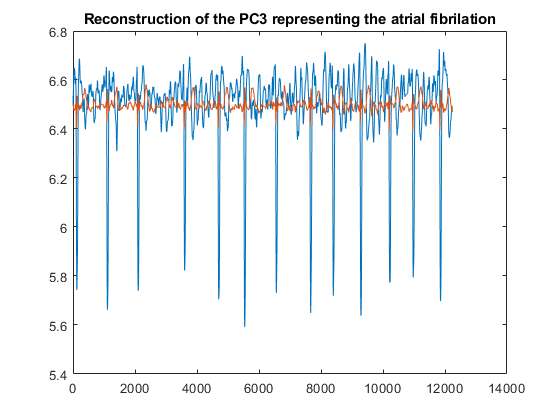

PC3_rec = A(:,3:4)*pinv(A(:,3:4))*data0;

figure()
plot((1:length(data)),data(7,:))
hold on
plot((1:length(PC3_rec)),PC3_rec(1,:)+mdata(7))
hold off
%legend('data','reconstructed PC3')
title('Reconstruction of the PC3 representing the atrial fibrilation')